# Exercise 1: Environment and Reward

## Humanoid Walker Model

This exercise uses a humanoid robot model created with [Simscape Multibody](docid:sm_doccenter#index). Each leg of the robot has torque-actuated revolute joints in the frontal hip, knee, and ankle. Each arm has two passive revolute joints in the frontal and sagittal shoulder. During the simulation, the model senses the contact forces, position and orientation of the torso, joint states, and forward position. 

Run the script `sm_humanoid_walker_rl_parameters` to load the model parameters.

sm_humanoid_walker_rl_parameters

Open the robot model to see how it is implemented.

mdl = 'HumanoidWalkerRobot';
open_system(mdl);

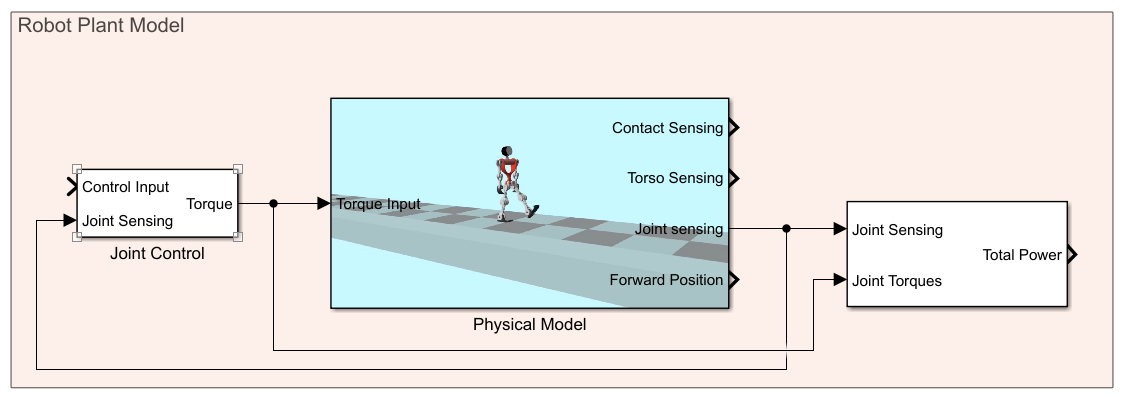

## Configure Model for Reinforcement Learning

You've been provided with the plant model for the humanoid robot, but we need to make a few changes to use this model for reinforcement learning:

- Define a reward function

- Create episode termination logic

- Add an [RL Agent](https://www.mathworks.com/help/reinforcement-learning/ref/rlagent.html) block and connect it appropriately

A custom simulink library has been provided to you for your convenience. Open the library.

lib = 'Humanoid_RL_Lib';
open_system(lib);

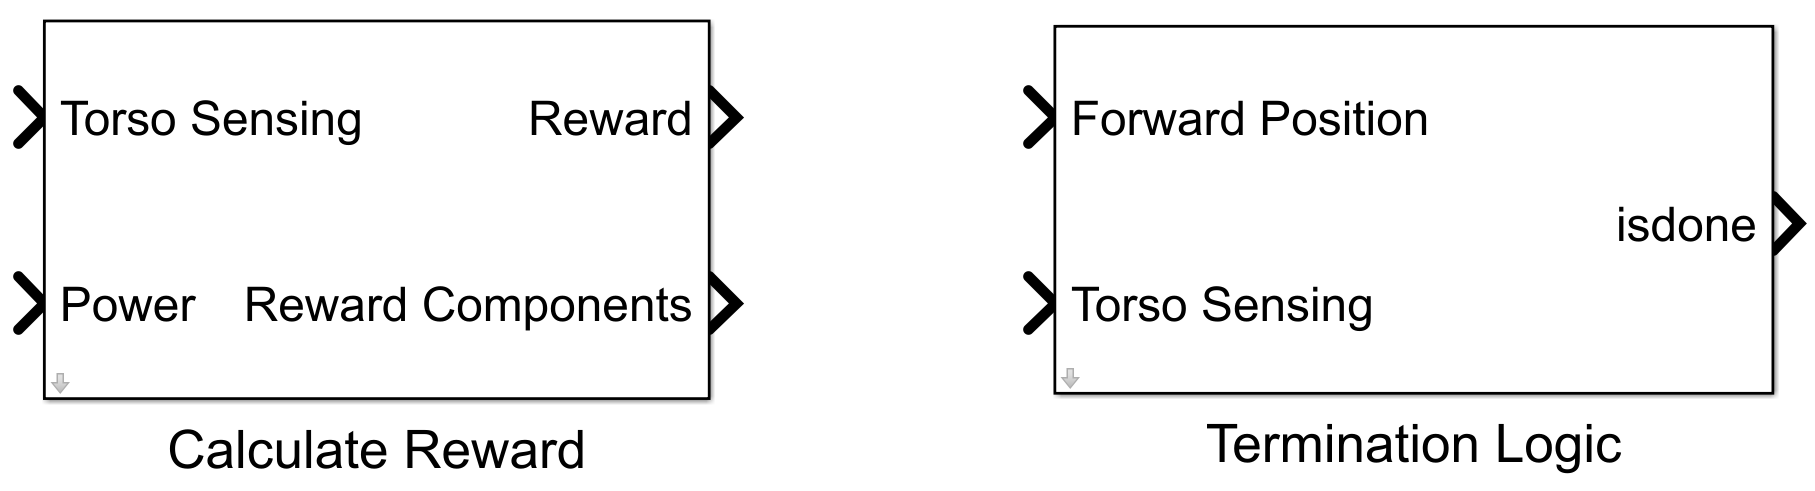

### Reward Function

Defining reward functions is often one of the more difficult steps in the reinforcement learning workflow. For this exercise, a reward function has already been provided for you: 


$$r_t =w_{1\;} v_{y\;} +w_2 t_s -w_{3\;} p-w_{4\;} \Delta z-w_{5\;} \Delta x$$


Here: 

- $v_y$ — Forward velocity (rewarded)

- $p$ — Power consumption (penalized)

- $\Delta z$ — Vertical displacement (penalized)

- $\Delta x$ — Lateral displacement (penalized) 

- $w_{1,\ldotp \ldotp \ldotp ,5}$: Weights, which represent the relative importance of each term in the reward function

Additional reward is provided for not falling over. Consequently, the total reward ($R$) for a single episode is:


$$R=\sum_{t=0}^T r_{t\;}$$


Here, $T$ is the time at which the simulation terminates.

Open the Calculate Reward subsystem provided to you to see how the reward function is defined in Simulink.

open_system([lib,'/Calculate Reward'],'force');

### Termination Logic

Here $T$ is the time at which the simulation terminates. The simulation terminates when the simulation time is reached or the robot falls. Falling is defined as:

- The robot drops below 0.5 m ($z$ direction).

- The robot moves laterally by more than 1 m ($x$ direction).

- The robot torso rotates by more than 30 degrees in any direction.

Open the Termination Logic subsystem provided to you to see how the termination criteria is defined in Simulink.

open_system([lib,'/Termination Logic'],'force');

### Add and Connect RL Agent

Add the **Calculate Reward** and **Termination Logic** subsystems to the **HumanoidWalkerRobot** model and connect their inputs accordingly. (Hint: You can add the subsystems via copy-paste or by simply dragging them from the library.)

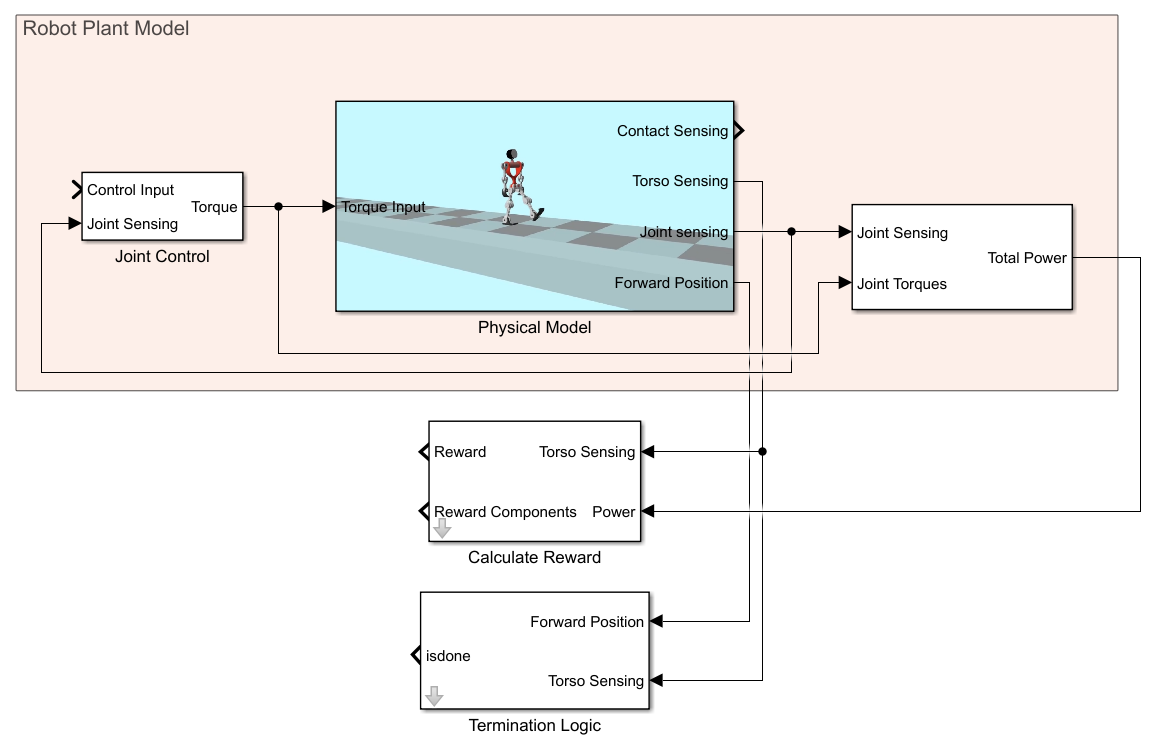

Finally, we need a way for our reinforcement learning agent to interface with our Simulink environment, which we do using the [RL Agent](https://www.mathworks.com/help/reinforcement-learning/ref/rlagent.html) block. 

- Add a **Mux** block to create the observation signal using the Contact Sensing, Torso Sensing, and Joint Sensing signals as the first three inputs.

- Add an **RL Agent** block and connect the **observation**, **reward**, and **isdone** ports appropriately (Hint: You can add this block by searching for it in the Library Browser or by simply clicking the model canvas and typing the name of the block). 

- Finally, add a **Unit Delay** block, connecting its input to the **action** port of the **RL Agent** block and its output as the fourth input to the **Mux** block.

The finished product should appear as follows. (Hint: You can use the shortcut Ctrl+I to flip Simulink blocks.)

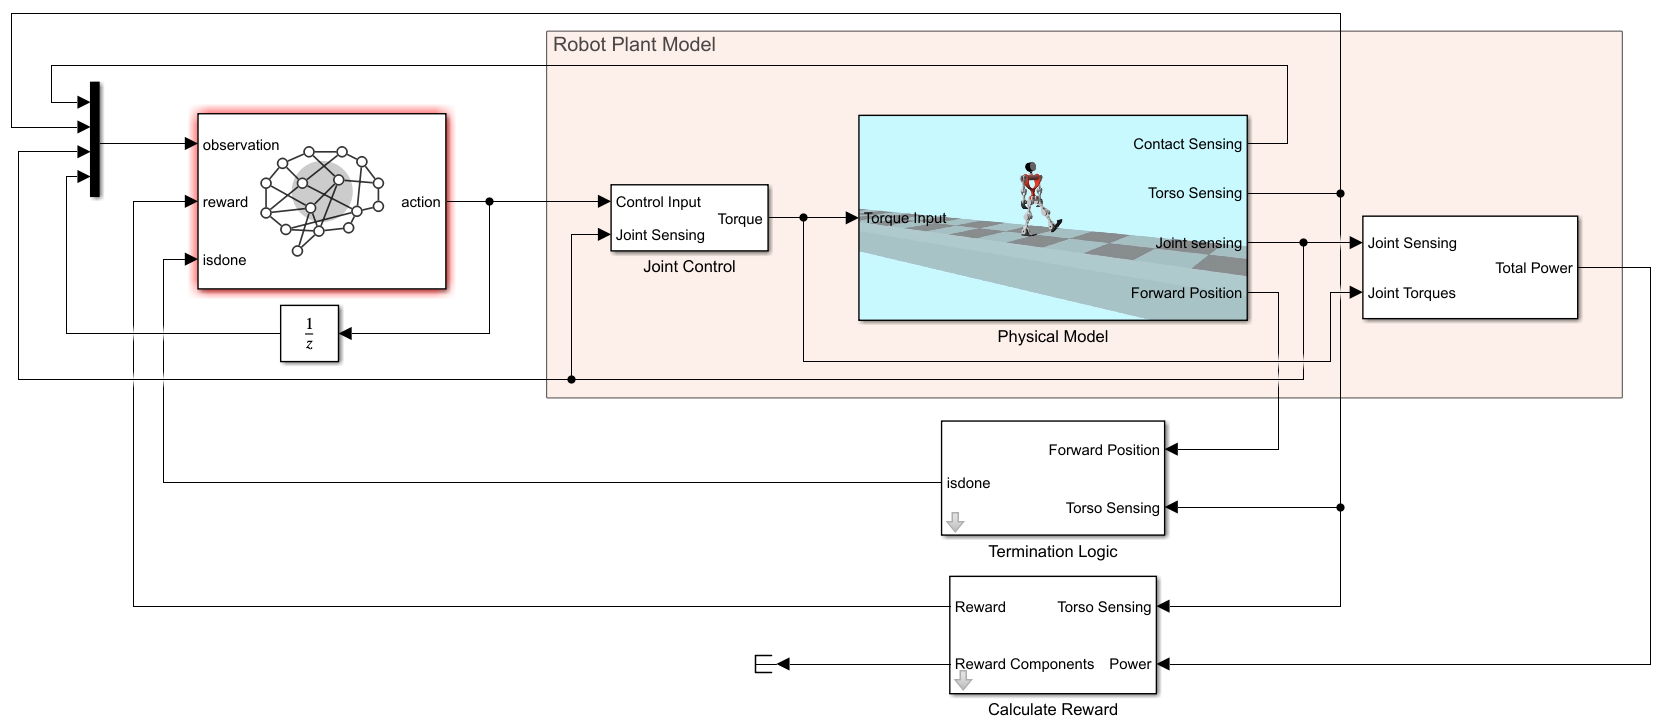

The RL Agent block is highlighted in red because we haven't yet define our agent. We will do this in the next exercise, so you can ignore this for now.

## Create Environment Object

Before creating our environment object, we must specify the interfaces for how the agent interacts with its environment. We have 6 actions, one input for each joint. These actions can take on a continuous range of values, so we will define our action specification using `rlNumericSpec`. We must also specify the upper and lower limits of the actions (scaled to the range [-1, 1] for this demo).

numAct       = 6;
actInfo      = rlNumericSpec([numAct 1],'LowerLimit',-1,'UpperLimit', 1);
actInfo.Name = 'jointDemands';

We must also define the observation space. In our model, we have 25 state measurements, and we also want to include the previous action as an observation, bringing the total number of observations to 31.

numObs       = 31;
obsInfo      = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

Finally, create the environment object and specify the location of the RL Agent block it relates to. 

load_system(mdl);
blockPath = [mdl,'/RL Agent'];
env = rlSimulinkEnv(mdl,blockPath,obsInfo,actInfo);

*Copyright 2019-2025 The MathWorks, Inc.*